clear;
clc;

J = 0.275e-7 % момент инерции ротора

J = 2.7500e-08

R = 46; % сопротивление
L = 1.17e-3 % индукция

L = 0.0012

Kw = 0.012 % постоянная ЭДС

Kw = 0.0120

Km = 12.3e-3 % постоянная момента

Km = 0.0123

Ihh = 7.88e-3 % ток холостого хода

Ihh = 0.0079

Whh = pi/30*9020 % rad/s (9020 rpm / 60 * 2 * pi) % скорость холостого хода

Whh = 944.5722

Lam = Km*Ihh/Whh % лямбда - коэффициент трения (??? переход от скорости к моменту???)

Lam = 1.0261e-07

Wnominal = pi/30 * 3620 % номинальная угловая скорость

Wnominal = 379.0855

Mhh = Km*Ihh

Mhh = 9.6924e-05


A = [-Lam/J Km/J; -Kw/L -R/L]

A = 1.0e+05 *

   -0.0000    4.4727
   -0.0001   -0.3932


B = [-1/J 0; 0 1/L]

B = 1.0e+07 *

   -3.6364         0
         0    0.0001


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



theta = [L; R; Kw; J; Lam]

theta =     0.0012
   46.0000
    0.0120
    0.0000
    0.0000



Amp = 6;
Bias = 6;
W = 6;
fi = 3.1415;

Const_input = [Amp Bias W fi];

[T, D] = eig(A)

T =     1.0000   -0.9962
   -0.0003    0.0873


D = 1.0e+04 *

   -0.0121         0
         0   -3.9199


Cc = ctrb(A,B)

Cc = 1.0e+08 *

   -0.3636         0    1.3568    3.8228
         0    0.0000    3.7296   -0.3360


rank(Cc)

ans = 2

expm(A)

T =     1.0000   -0.9962
   -0.0003    0.0873


D = 1.0e+04 *

   -0.0121         0
         0   -3.9199


ans = 1.0e+08 *

   -0.3636         0    1.3568    3.8228
         0    0.0000    3.7296   -0.3360


ans = 1.0e-51 *

    0.0356    0.4061
   -0.0000   -0.0001


T*expm(D)*inv(T)

ans = 1.0e-51 *

    0.0356    0.4061
   -0.0000   -0.0001



syms t

x(t) = T*expm(D*t)*inv(T)*[600;0];
x(t) = vpa(x(t), 5)

$$x(t) = \left(\begin{array}{c} 601.79699178528971970081329345703\,{\mathrm{e}}^{-120.77068907317880075424909591675\,t}-1.7969917852728940488304942846298\,{\mathrm{e}}^{-39199.199955619871616363525390625\,t}\\ 0.15747424523826225595257710665464\,{\mathrm{e}}^{-39199.199955619871616363525390625\,t}-0.15747424523826225595257710665464\,{\mathrm{e}}^{-120.77068907317880075424909591675\,t} \end{array}\right)$$


dt = 0.000001;
ts = 0;
tf = 1;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
1000000

t = linspace(ts, tf, num_of_steps);
w_arr = zeros(1, num_of_steps);
I_arr = zeros(1, num_of_steps);

for i = 1:num_of_steps/1000
    tc = t(i);
    xc = double(x(tc));
    w_arr(i) = xc(1);
    I_arr(i) = xc(2);
end

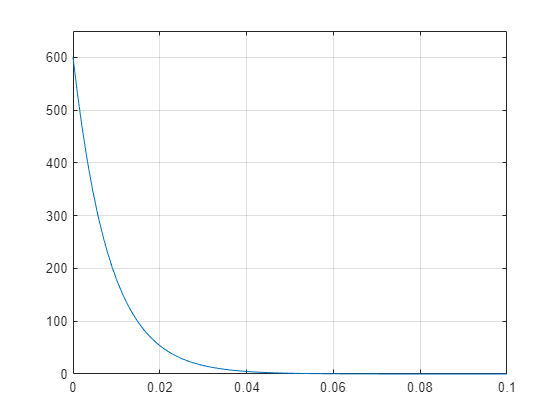

figure
fplot([1 0]*x)
xlim([0 0.1])
ylim([0 650])
grid on

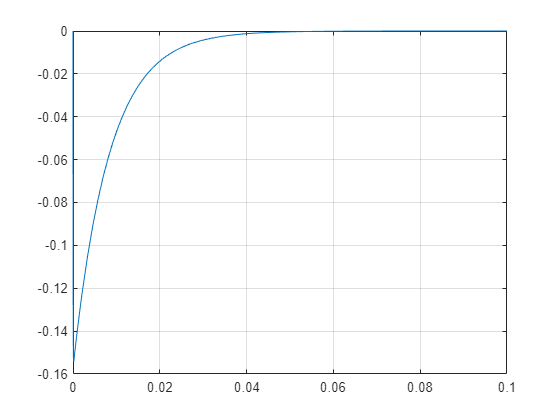


figure
fplot([0 1]*x)
xlim([0 0.1])
ylim([-0.16 0])
grid on

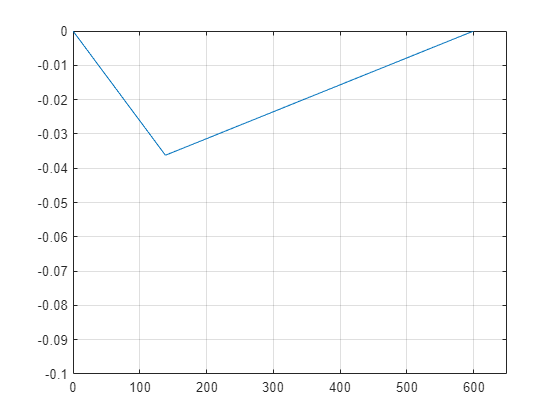


% figure
% fplot([1 0]*x, [0 1]*x)
% xlim([0 650])
% ylim([-0.1 0])
% grid on

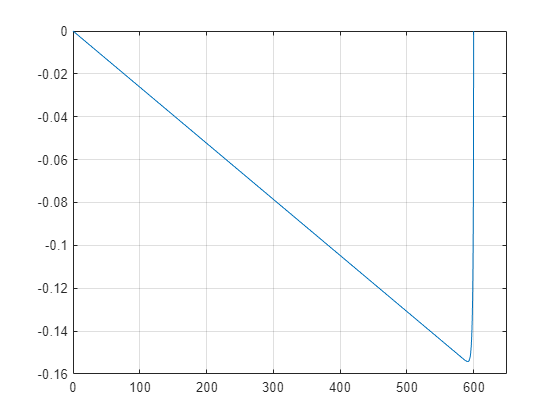


figure
plot(w_arr, I_arr)
xlim([0 650])
ylim([-0.16 0])
grid on

### Continous form

dt = 0.000001;
ts = 0;
tf = 5;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
5000000

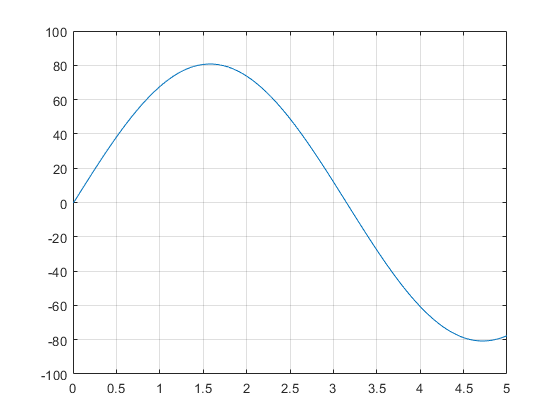

t = linspace(ts, tf, num_of_steps);

% x = [w I]'
% u = [M u]
x = [0 0]';
u = [0 12]';
x_arr = zeros(2, num_of_steps);

for i = 1:num_of_steps
    u = [0 sin(dt*double(i))]';
    dx = A*x + B*u;
    x = x + dx*dt;
    x_arr(:, i) = x;
end

x_arr1 = x_arr;
t1 = t;

figure
plot(t, x_arr(1, :))
grid on

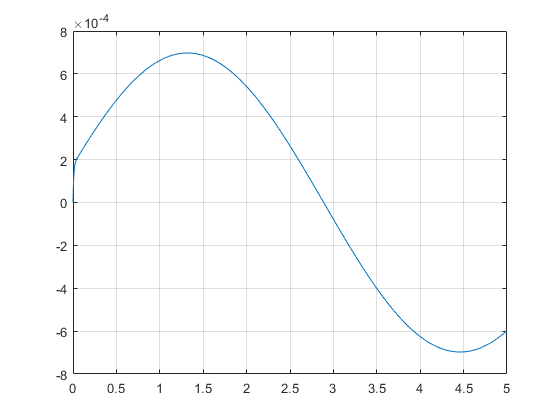

plot(t, x_arr(2, :))
grid on
% xlim([0 0.01])
xlim auto
ylim auto

### Discrete form

dt = 0.00001;
ts = 0;
tf = 5;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
500000

t = linspace(ts, tf, num_of_steps);

% x = [w I]'
% u = [M u]
x = [0 0]';
u = [0 12]';
x_arr = zeros(2, num_of_steps);

for i = 1:num_of_steps-1
    u = [0 sin(dt*double(i))]';
    x_arr(:, i+1) = (eye(2) + A*dt)*x_arr(:, i) + B*u*dt;
end

figure
plot(t, x_arr(1, :))
grid on

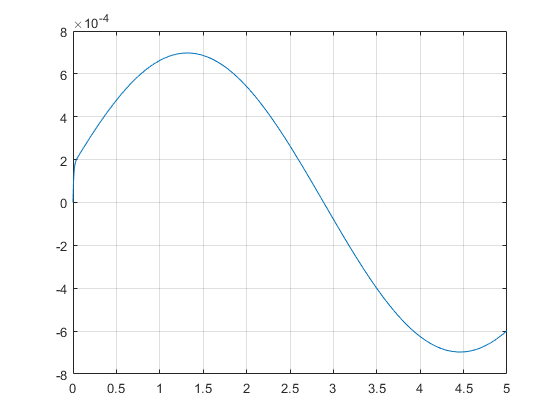

plot(t, x_arr(2, :))
grid on

### Discrete form 2

dt = 0.000001;
ts = 0;
tf = 5;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
5000000

t = linspace(ts, tf, num_of_steps);

% x = [w I]'
% u = [M u]
x = [0 0]';
u = [0 12]';
x_arr = zeros(2, num_of_steps);

[T, D] = eig(A)

T =     1.0000   -0.9962
   -0.0003    0.0873


D = 1.0e+04 *

   -0.0121         0
         0   -3.9199


At = expm(A*dt)

At =     1.0000    0.4386
   -0.0000    0.9614


eye(2) + A*dt

ans =     1.0000    0.4473
   -0.0000    0.9607


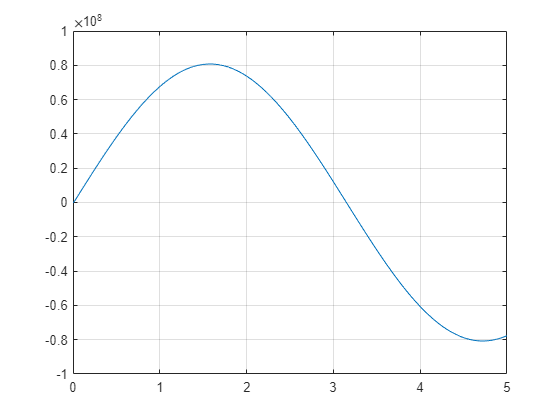


for i = 1:num_of_steps-1
    u = [0 sin(dt*double(i))]';
    x_arr(:, i+1) = At*x_arr(:, i)+B*u;
%     dx = A*x + B*u;
%     x = x + dx*dt;
%     x_arr(:, i) = x;
end

x_arr_d2 = x_arr;
t_d2 = t;

figure
plot(t, x_arr(1, :))
grid on

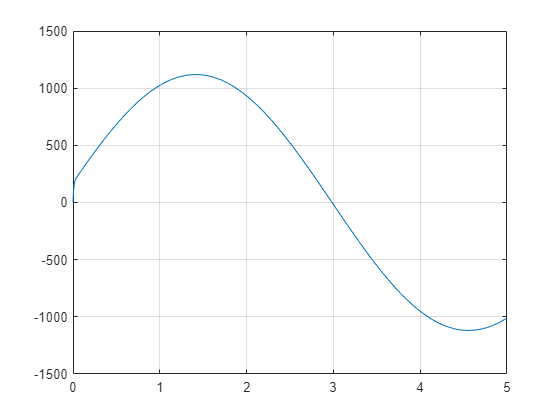

plot(t, x_arr(2, :))
grid on
% xlim([0 0.01])
xlim auto
ylim auto

### Discrete form full u=const

dt = 0.00001;
ts = 0;
tf = 1;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
100000

t = linspace(ts, tf, num_of_steps);

% x = [w I]'
% u = [M u]
x = [0 0]';
u = [0 12]';
x_arr = zeros(2, num_of_steps);

for i = 1:num_of_steps-1
    u = [0 sin(dt*double(i))]';
    x_arr(:, i+1) = x_arr(:, i) + expm(A*double(i)*dt)*(expm(A*dt)-eye(2))*inv(A)*B*u;
end

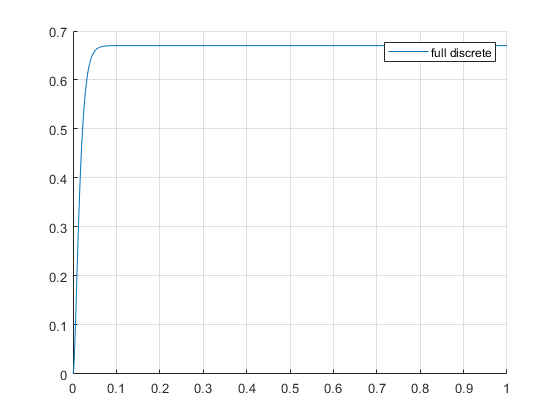

figure
hold on
plot(t, x_arr(1, :))
% plot(t1, x_arr1(1, :), '--')
% xlim([0 0.1])
hold off
grid on
legend('full discrete', 'original')


figure
hold on
plot(t, x_arr(2, :))
% plot(t1, x_arr1(2, :), '--')
hold off
% xlim([0 0.1])
legend('full discrete', 'original')

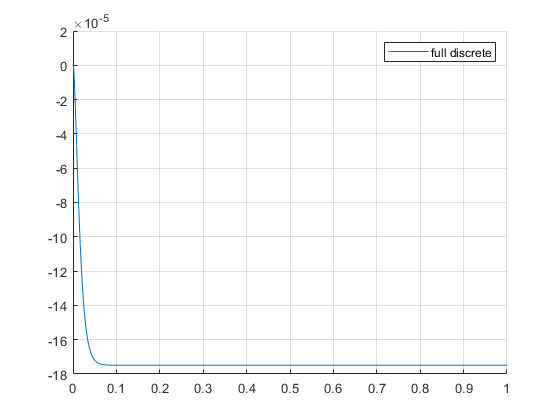

grid on

### Discrete form full u(t)

dt = 0.00001;
ts = 0;
tf = 0.1;
num_of_steps = uint32((tf-ts)/dt)

num_of_steps = uint32
10000

t = linspace(ts, tf, num_of_steps);

% x = [w I]'
% u = [M u]
x = [0 0]';
u = [0 12]';
x_arr = zeros(2, num_of_steps);
u_arr = zeros(2, num_of_steps);
sum_u_k1 = [0 0]';
sum_u_k = [0 0]';

for i = 1:num_of_steps-1
    u = [0 sin(dt*double(i))]'; 

    sum_u_k1 = sum_u_k1 + B*expm(-A*double(i)*dt) * u;

    x_arr(:, i+1) = x_arr(:, i) + expm(A*double(i)*dt) * ( expm(A*dt)* sum_u_k1 - sum_u_k);

    sum_u_k = sum_u_k + B*expm(-A*double(i)*dt) * u;
end

Am = eye(2)*1.5

Am =     1.5000         0
         0    1.5000


syms x1 x2
xm = [x1; x2]

$$xm = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$


xmn = Am*xm

$$xmn = \left(\begin{array}{c} \frac{3\,x_{1}}{2}\\ \frac{3\,x_{2}}{2} \end{array}\right)$$

det(Am)

ans = 2.2500

eig(Am)

ans =     1.5000
    1.5000


Am = [3 -1;
      -1 3]

Am =      3    -1
    -1     3


[T,D] = eig(Am) 

T =    -0.7071   -0.7071
   -0.7071    0.7071


D =      2     0
     0     4



syms a b c d t

Am = [a b; c d]

$$Am = \left(\begin{array}{cc} a & b\\ c & d \end{array}\right)$$

[T,D] = eig(Am) 

$$T = \left(\begin{array}{cc} \frac{\frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}}{c}-\frac{d}{c} & \frac{\frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}}{c}-\frac{d}{c}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} & 0\\ 0 & \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

di = diag(D)

$$di = \left(\begin{array}{c} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\\ \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

etothed = exp(di*t)

$$etothed = \left(\begin{array}{c} {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)}\\ {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)} \end{array}\right)$$

etotheD = diag(etothed)

$$etotheD = \left(\begin{array}{cc} {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)} & 0\\ 0 & {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)} \end{array}\right)$$


syms a b c d t;
Am = [a b; c d];
[T,D] = eig(Am);
expm(D*t)

$$ans = \left(\begin{array}{cc} {\mathrm{e}}^{\frac{t\,\left(a+d-\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}\right)}{2}} & 0\\ 0 & {\mathrm{e}}^{\frac{t\,\left(a+d+\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}\right)}{2}} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)} & 1\\ 1 & {\mathrm{e}}^{t\,\left(\frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\right)} \end{array}\right)$$